clf;
homedir='/Users/editabulovaite/Documents/PhD_Year3/Data';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';
startRow = 2;

data=dir('for_plotting.csv');
data = readtable(data.name);


mean_3week = data(:,2);
mean_3week = table2array(mean_3week);
SD_3week = data(:,5);
SD_3week = table2array(SD_3week);
SDs_3week = [SD_3week SD_3week];


mean_3month = data(:,3);
mean_3month = table2array(mean_3month);
SD_3month = data(:,6);
SD_3month = table2array(SD_3month);
SDs_3month = [SD_3month SD_3month];

mean_18month = data(:,4);
mean_18month = table2array(mean_18month);
SD_18month = data(:,7);
SD_18month = table2array(SD_18month);
SDs_18month = [SD_18month SD_18month];

regions=data(:,1);
regions = table2array(regions);
regions=categorical(regions);
nregions = length(regions);
nrg = 1:1:nregions;

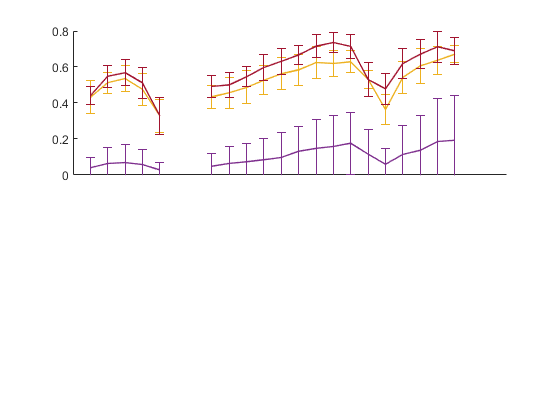

subplot(2,1,1)
errorbar(mean_3month,SD_3month,"Color",[0.9290 0.6940 0.1250]);
hold on
plot(mean_3month,'-',"LineWidth",1,"Color",[0.9290 0.6940 0.1250]); 
hold on
errorbar(mean_3week,SD_3week,"Color",[0.4940 0.1840 0.5560]);
hold on
plot(mean_3week,'-',"LineWidth",1,"Color",[0.4940 0.1840 0.5560]); 
hold on
errorbar(mean_18month,SD_18month,"Color",[0.6350 0.0780 0.1840]);
hold on
plot(mean_18month,'-',"LineWidth",1,"Color",[0.6350 0.0780 0.1840]); 
set(gca,'xtick',[])
ylim([0 0.8])
box off
hold off
saveas(gca,'CA1_subs_lifespan_turnover','eps')
saveas(gca,'CA1_subs_lifespan_turnover','png')